## Stałoprzecinkowe testy na pojedynczych liczbach

clear all; close all;
z = 1;
c = 8;
u = 0;
word = 1 + c + u;

R = 122;

R_fix = fi(R,z,word,u)

R_fix =    122

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 9
        FractionLength: 0

G = 44;
G_fix = fi(G,z,word,u)

G_fix =     44

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 9
        FractionLength: 0

B = 98;
B_fix = fi(B,z,word,u)

B_fix =     98

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 9
        FractionLength: 0

M = [0.299 0.587 0.114;
    -0.168736 -0.331264 0.5;
    0.5 -0.418688 -0.081312];

A = [0;
    128;
    128];

zw = 1;
cw = 0;
uw = 17;
wordw = 1 + cw + uw;
s = size(M);
for r = 1:s(1)
    for c = 1:s(2)
        mfixed = fi(M(r,c),zw,wordw,uw)
        M_fix(r,c) = fi(M(r,c),zw,wordw,uw);
        hex(fi(M(r,c),zw,wordw,uw))
    end
    
    afixed = fi(A(r),z,word,u)
    A_fix(r) = fi(A(r),z,word,u);
    hex(fi(A(r),z,word,u))
end

mfixed =     0.2990

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 18
        FractionLength: 17

ans = '09917'

mfixed =     0.5870

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 18
        FractionLength: 17

ans = '12c8b'

mfixed =     0.1140

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 18
        FractionLength: 17

ans = '03a5e'

afixed =      0

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 9
        FractionLength: 0

ans = '000'

mfixed =    -0.1687

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 18
        FractionLength: 17

ans = '3a99b'

mfixed =    -0.3313

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 18
        FractionLength: 17

ans = '35665'

mfixed =     0.5000

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 18
        FractionLength: 17

ans = '10000'

afixed =    128

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 9
        FractionLength: 0

ans = '080'

mfixed =     0.5000

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 18
        FractionLength: 17

ans = '10000'

mfixed =    -0.4187

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 18
        FractionLength: 17

ans = '329a2'

mfixed =    -0.0813

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 18
        FractionLength: 17

ans = '3d65e'

afixed =    128

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 9
        FractionLength: 0

ans = '080'

M_fix

M_fix =     0.2990    0.5870    0.1140
   -0.1687   -0.3313    0.5000
    0.5000   -0.4187   -0.0813

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 18
        FractionLength: 17

A_fix

A_fix =      0   128   128

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 9
        FractionLength: 0

ntBP = numerictype(1,8,0);


for r = 1:s(1)
    if r == 1
        Y = quantize(M_fix(r,1)*R_fix,ntBP) + quantize(M_fix(r,2)*G_fix,ntBP) + quantize(M_fix(r,3)*B_fix,ntBP) + A_fix(r);
    elseif r == 2
        Cb = quantize(M_fix(r,1)*R_fix,ntBP) + quantize(M_fix(r,2)*G_fix,ntBP) + quantize(M_fix(r,3)*B_fix,ntBP) + A_fix(r);
    else
        Cr = quantize(M_fix(r,1)*R_fix,ntBP) + quantize(M_fix(r,2)*G_fix,ntBP) + quantize(M_fix(r,3)*B_fix,ntBP) + A_fix(r);
    end
end

YCbCr(1) = Y;
YCbCr(2) = Cb;
YCbCr(3) = Cr;
YCbCr

YCbCr =     72   141   162

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 11
        FractionLength: 0

## Zmiennoprzecinkowe testy na pojedynczych liczbach

R = 122;
G = 44;
B = 98;

M = [0.299 0.587 0.114;
    -0.168736 -0.331264 0.5;
    0.5 -0.418688 -0.081312];

A = [0;
    128;
    128];

for r = 1:s(1)
    if c == 1
        Y = M(r,1)*R + M(r,2)*G + M(r,3)*B + A(c);
    elseif c == 2
        Cb = M(r,1)*R + M(r,2)*G + M(r,3)*B + A(c);
    else
        Cr = M(r,1)*R + M(r,2)*G + M(r,3)*B + A(c);
    end

end


YCbCr(1) = Y;
YCbCr(2) = Cb;
YCbCr(3) = Cr;

YCbCr

YCbCr =     72   141   163

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 11
        FractionLength: 0

## Ręka na liczbach stałoprzecinkowych - model

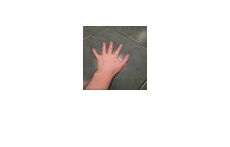

clear all; close all;
reka = imread('reka.ppm');
imshow(reka);

z = 1;
c = 8;
u = 0;
word = 1 + c + u;

R = reka(:,:,1);
R_fix = fi(R,z,word,u)

R_fix =     90    90    89    85    81    81    87    94    89    89    91    93    96    98    98    98   104   100    98   102   106   102    89    76    81    85    90    95    96    94    91    88    97    95    92    90    96   102    99    92    90    93    93    89    89    92    91    88    88    84    82    87    89    87    84    84    89    88    86    86    85    85    83    82
    94    93    92    91    90    92    94    96    95    94    94    95    98   100   101   102   103   101    99    98    98    96    91    87    97    95    93    91    90    91    91    92    86    93    98   101   102   102    95    87    89    92    92    90    90    94    94    91    88    84    84    88    91    88    86    86    87    90    92    91    88    87    88    89
    96    94    93    94    97    98    97    96    94    94    93    94    95    97    99   100    96    98    98    95    92    93    98   103   109   106   101    95    92    92    92    93    95    99   102   100    97

G = reka(:,:,2);
G_fix = fi(G,z,word,u)

G_fix =     90    90    89    85    81    81    87    94    89    89    91    93    96    98    98    98   105   101    99   103   107   103    90    77    82    86    91    96    97    95    92    89    99    97    94    92    98   104   101    94    92    95    95    91    91    94    93    90    86    82    82    87    89    87    84    84    91    90    88    88    87    87    87    86
    94    93    92    91    90    92    94    96    95    94    94    95    98   100   101   102   104   102   100    99    99    97    92    88    98    96    94    92    91    92    92    93    88    95   100   103   104   104    97    89    91    94    94    92    92    96    96    93    88    84    84    88    91    88    86    86    89    92    94    93    90    89    90    93
    96    94    93    94    97    98    97    96    94    94    93    94    95    97    99   100    97    99    99    96    93    94    99   104   110   107   102    96    93    93    93    94    97   101   104   102    99

B = reka(:,:,3);
B_fix = fi(B,z,word,u)

B_fix =     78    78    77    73    69    69    75    82    77    77    79    81    84    86    86    86    91    87    85    89    93    89    76    63    68    72    77    82    83    81    78    75    86    84    81    79    85    91    88    81    79    82    82    78    78    81    80    77    74    70    70    75    77    75    72    72    78    77    75    75    74    74    73    72
    82    81    80    79    78    80    82    84    83    82    82    83    86    88    89    90    90    88    86    85    85    83    78    74    84    82    80    78    77    78    78    79    75    82    87    90    91    91    84    76    78    81    81    79    79    83    83    80    76    72    72    76    79    76    74    74    76    79    81    80    77    76    77    79
    84    82    81    82    85    86    85    84    82    82    81    82    83    85    87    88    83    85    85    82    79    80    85    90    96    93    88    82    79    79    79    80    84    88    91    89    86

M = [0.299 0.587 0.114;
    -0.168736 -0.331264 0.5;
    0.5 -0.418688 -0.081312];

A = [0;
    128;
    128];

zw = 1;
cw = 0;
uw = 17;
wordw = 1 + cw + uw;
s = size(M);
for r = 1:s(1)
    for c = 1:s(2)
        mfixed = fi(M(r,c),zw,wordw,uw)
        M_fix(r,c) = fi(M(r,c),zw,wordw,uw);
        hex(fi(M(r,c),zw,wordw,uw))
    end
    
    afixed = fi(A(r),z,word,u)
    A_fix(r) = fi(A(r),z,word,u);
    hex(fi(A(r),z,word,u))
end

mfixed =     0.2990

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 18
        FractionLength: 17

ans = '09917'

mfixed =     0.5870

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 18
        FractionLength: 17

ans = '12c8b'

mfixed =     0.1140

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 18
        FractionLength: 17

ans = '03a5e'

afixed =      0

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 9
        FractionLength: 0

ans = '000'

mfixed =    -0.1687

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 18
        FractionLength: 17

ans = '3a99b'

mfixed =    -0.3313

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 18
        FractionLength: 17

ans = '35665'

mfixed =     0.5000

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 18
        FractionLength: 17

ans = '10000'

afixed =    128

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 9
        FractionLength: 0

ans = '080'

mfixed =     0.5000

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 18
        FractionLength: 17

ans = '10000'

mfixed =    -0.4187

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 18
        FractionLength: 17

ans = '329a2'

mfixed =    -0.0813

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 18
        FractionLength: 17

ans = '3d65e'

afixed =    128

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 9
        FractionLength: 0

ans = '080'

M_fix

M_fix =     0.2990    0.5870    0.1140
   -0.1687   -0.3313    0.5000
    0.5000   -0.4187   -0.0813

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 18
        FractionLength: 17

A_fix

A_fix =      0   128   128

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 9
        FractionLength: 0

ntBP = numerictype(1,8,0);


for r = 1:s(1)
    if r == 1
        Y = quantize(M_fix(r,1)*R_fix,ntBP) + quantize(M_fix(r,2)*G_fix,ntBP) + quantize(M_fix(r,3)*B_fix,ntBP) + A_fix(r);
    elseif r == 2
        Cb = quantize(M_fix(r,1)*R_fix,ntBP) + quantize(M_fix(r,2)*G_fix,ntBP) + quantize(M_fix(r,3)*B_fix,ntBP) + A_fix(r);
    else
        Cr = quantize(M_fix(r,1)*R_fix,ntBP) + quantize(M_fix(r,2)*G_fix,ntBP) + quantize(M_fix(r,3)*B_fix,ntBP) + A_fix(r);
    end
end

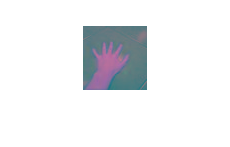

% Identyczne wyniki jak z funkcji z Matlaba
YCbCr(:,:,1) = Y;
YCbCr(:,:,2) = Cb;
YCbCr(:,:,3) = Cr;
imshow(uint8(YCbCr));

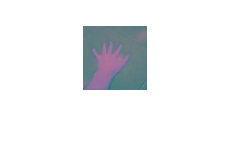

% Porównanie z funkcją z Matlaba
sds = imread("reka.ppm");
d = rgb2ycbcr(sds);
imshow(d)

## Ręka na liczbach zmiennoprzecinkowych

reka = imread('reka.ppm');
imshow(reka);

R = reka(:,:,1);
G = reka(:,:,2);
B = reka(:,:,3);

M = [0.299 0.587 0.114;
    -0.168736 -0.331264 0.5;
    0.5 -0.418688 -0.081312];

A = [0;
    128;
    128];

for r = 1:s(1)
    if c == 1
        Y = M(r,1)*R + M(r,2)*G + M(r,3)*B + A(c);
    elseif c == 2
        Cb = M(r,1)*R + M(r,2)*G + M(r,3)*B + A(c);
    else
        Cr = M(r,1)*R + M(r,2)*G + M(r,3)*B + A(c);
    end

end


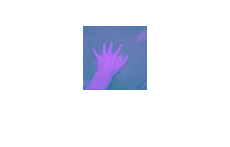

% Porównanie
% Zauważalna jest różnica - obraz na liczbach typu duble jest jaśniejszy
YCbCr(:,:,1) = Y;
YCbCr(:,:,2) = Cb;
YCbCr(:,:,3) = Cr;
new = uint8(YCbCr);
imshow(new);

sds = imread("reka.ppm");
d = rgb2ycbcr(sds);
imshow(d)

## Porównanie symulacji z wersją z Matlaba

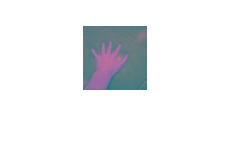

from_vivado= imread("out_00.ppm");
imshow(from_vivado)

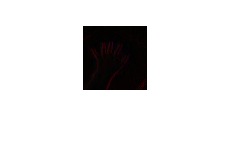

% Brak różnicy pomiędzy obrazem z Matlaba a obrazem z symulacji
comp = imabsdiff(d,from_vivado);
imshow(comp)

imwrite(d,"reka_po_ycbcr.ppm")